โค้ดค่าดิบของ Northcap

% clc; clear; close all;
% 
% %% =========================================================
% % 1. MODE SELECTOR (เลือกโหมดทำงานตรงนี้)
% % ==========================================================
% plot_mode  = 2;     % 1 = พล็อตทีละ 1 การทดลอง | 2 = พล็อตรวมทั้ง 4 การทดลอง
% active_exp = 'SNC';  % สำหรับ mode 1 เลือก: 'NC' | 'NNC' | 'SC' | 'SNC'
% 
% %% =========================================================
% % 2. FILE PATHS ALL EXPERIMENTS
% % ==========================================================
% NC  = {'NorthCap\NC1\outofnorthcap1.mat'; 'NorthCap\NC2\outofnorthcap2.mat'; 'NorthCap\NC3\outofnorthcap3.mat'};
% NNC = {'NorthNoCap\NNC1\outofnorthnocap1.mat'; 'NorthNoCap\NNC2\outofnorthnocap2.mat'; 'NorthNoCap\NNC3\outofnorthnocap3.mat'};
% SC  = {'SouthCap\SC1\outofsouthcap1.mat'; 'SouthCap\SC2\outsouthcap2.mat'; 'SouthCap\SC3\outsouthcap3.mat'};
% SNC = {'SouthNoCap\SNC1\outofsouthnocap1.mat'; 'SouthNoCap\SNC2\outofsouthnocap2.mat'; 'SouthNoCap\SNC3\outofsouthnnocap3.mat'};
% 
% bg_color = [0.12 0.12 0.12];
% 
% %% =========================================================
% % 3. RUN PROGRAM ACCORDING TO MODE
% % ==========================================================
% if plot_mode == 1
%     % ------------------------------------------------------
%     % MODE 1: SINGLE EXPERIMENT
%     % ------------------------------------------------------
%     switch upper(active_exp)
%         case 'NC',  active_files = NC;  exp_title = 'North - Cap';     line_color = [0 0.65 1];
%         case 'NNC', active_files = NNC; exp_title = 'North - No Cap';  line_color = [1 0.45 0.1];
%         case 'SC',  active_files = SC;  exp_title = 'South - Cap';     line_color = [1 0.85 0.2];
%         case 'SNC', active_files = SNC; exp_title = 'South - No Cap';  line_color = [0.75 0.35 1];
%         otherwise, error('Invalid active_exp! Choose NC, NNC, SC, or SNC');
%     end
% 
%     checkFiles(active_files);
%     [dist_avg, mean_avg] = read3trial(active_files);
% 
%     figure('Color', bg_color);
%     plot(dist_avg, mean_avg, '-o', ...
%         'Color', line_color, 'LineWidth', 2, 'MarkerSize', 7, ...
%         'MarkerEdgeColor', line_color, 'MarkerFaceColor', bg_color, ...
%         'DisplayName', exp_title);
% 
%     xlabel('Distance (mm)', 'Color', 'w', 'FontSize', 13, 'FontWeight', 'bold');
%     ylabel('Mean Raw Sensor Value (12-bit)', 'Color', 'w', 'FontSize', 13, 'FontWeight', 'bold');
%     title(['Average of 3 Trials: ' exp_title], 'Color', 'w', 'FontSize', 15, 'FontWeight', 'bold');
% 
%     ylim([0 4500]); yticks(0:500:4500); grid on; grid minor;
%     ax = gca; ax.Color = [0.08 0.08 0.08]; ax.XColor = [0.75 0.75 0.75]; ax.YColor = [0.75 0.75 0.75];
%     ax.GridColor = [0.35 0.35 0.35]; ax.GridAlpha = 0.5; ax.FontSize = 12;
%     legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
% 
%     saveas(gcf, ['Average_' active_exp '.fig']);
%     fprintf('\nFinished! Saved as: Average_%s.fig\n', active_exp);
% 
% elseif plot_mode == 2
%     % ------------------------------------------------------
%     % MODE 2: ALL 4 EXPERIMENTS
%     % ------------------------------------------------------
%     checkFiles(NC); checkFiles(NNC); checkFiles(SC); checkFiles(SNC);
% 
%     [NC_dist, NC_mean]   = read3trial(NC);
%     [NNC_dist, NNC_mean] = read3trial(NNC);
%     [SC_dist, SC_mean]   = read3trial(SC);
%     [SNC_dist, SNC_mean] = read3trial(SNC);
% 
%     figure('Color', bg_color);
%     plot(NC_dist, NC_mean, '-o', 'Color', [0 0.65 1], 'LineWidth', 2, 'MarkerSize', 6, 'MarkerEdgeColor', [0 0.65 1], 'MarkerFaceColor', bg_color, 'DisplayName', 'North - Cap'); hold on;
%     plot(NNC_dist, NNC_mean, '-o', 'Color', [1 0.45 0.1], 'LineWidth', 2, 'MarkerSize', 6, 'MarkerEdgeColor', [1 0.45 0.1], 'MarkerFaceColor', bg_color, 'DisplayName', 'North - No Cap');
%     plot(SC_dist, SC_mean, '-o', 'Color', [1 0.85 0.2], 'LineWidth', 2, 'MarkerSize', 6, 'MarkerEdgeColor', [1 0.85 0.2], 'MarkerFaceColor', bg_color, 'DisplayName', 'South - Cap');
%     plot(SNC_dist, SNC_mean, '-o', 'Color', [0.75 0.35 1], 'LineWidth', 2, 'MarkerSize', 6, 'MarkerEdgeColor', [0.75 0.35 1], 'MarkerFaceColor', bg_color, 'DisplayName', 'South - No Cap');
% 
%     xlabel('Distance (mm)', 'Color', 'w', 'FontSize', 13, 'FontWeight', 'bold');
%     ylabel('Mean Raw Sensor Value (12-bit)', 'Color', 'w', 'FontSize', 13, 'FontWeight', 'bold');
%     title('Average of 4 Experiments (3 Trials Each)', 'Color', 'w', 'FontSize', 15, 'FontWeight', 'bold');
% 
%     ylim([0 4500]); yticks(0:500:4500); grid on; grid minor;
%     ax = gca; ax.Color = [0.08 0.08 0.08]; ax.XColor = [0.75 0.75 0.75]; ax.YColor = [0.75 0.75 0.75];
%     ax.GridColor = [0.35 0.35 0.35]; ax.GridAlpha = 0.5; ax.FontSize = 12;
%     legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
% 
%     saveas(gcf, 'Average_4_Experiments.fig');
%     fprintf('\nFinished! Saved as: Average_4_Experiments.fig\n');
% else
%     error('Invalid plot_mode! Use 1 or 2.');
% end
% 
% %% =========================================================
% % LOCAL FUNCTIONS (ประกาศไว้ล่างสุดของไฟล์เพียงชุดเดียว)
% % ==========================================================
% function [distance_avg, mean_avg] = read3trial(files)
%     all_distance = cell(3,1);
%     all_mean = cell(3,1);
% 
%     for k = 1:3
%         data = load(files{k});
%         names = fieldnames(data);
%         out = data.(names{1});
% 
%         raw_signal = out.Sensor_raw_log;
%         raw = double(raw_signal.Data(:));
%         t_raw = double(raw_signal.Time(:));
% 
%         distance_signal = out.Distance_log;
%         d_log = double(distance_signal.Data(:));
%         t_distance = double(distance_signal.Time(:));
% 
%         if length(d_log) == 1
%             distance_all = repmat(d_log, length(raw), 1);
%         else
%             distance_all = interp1(t_distance, d_log, t_raw, 'previous', 'extrap');
%         end
% 
%         distance_all = round(distance_all, 4); % ป้องกัน Floating-Point Mismatch
% 
%         valid = isfinite(raw) & isfinite(distance_all);
%         raw = raw(valid);
%         distance_all = distance_all(valid);
% 
%         distance = unique(distance_all, 'stable');
%         n = length(distance);
% 
%         mean_raw = zeros(n,1);
%         for i = 1:n
%             idx = distance_all == distance(i);
%             data_i = raw(idx);
%             if isempty(data_i)
%                 mean_raw(i) = NaN;
%             else
%                 mean_raw(i) = mean(data_i);
%             end
%         end
% 
%         [distance_sort, order] = sort(distance);
%         mean_sort = mean_raw(order);
% 
%         all_distance{k} = distance_sort;
%         all_mean{k} = mean_sort;
%     end
% 
%     distance_avg = all_distance{1};
%     for k = 2:3
%         distance_avg = intersect(distance_avg, all_distance{k});
%     end
% 
%     mean_avg = zeros(length(distance_avg), 1);
%     for i = 1:length(distance_avg)
%         d = distance_avg(i);
%         value = zeros(3,1);
%         for k = 1:3
%             idx = all_distance{k} == d;
%             if any(idx)
%                 value(k) = all_mean{k}(idx);
%             else
%                 value(k) = NaN;
%             end
%         end
%         mean_avg(i) = mean(value, 'omitnan');
%     end
% 
%     [distance_avg, order] = sort(distance_avg);
%     mean_avg = mean_avg(order);
% end
% 
% function checkFiles(files)
%     for k = 1:length(files)
%         if ~isfile(files{k})
%             error('File not found:\n%s\n\nCurrent Folder:\n%s', files{k}, pwd);
%         end
%     end
% end

แปลงเป็นแรงดันและค่าสนามแม่เหล็กจากค่าดิบ

% clc; clear; close all;
% 
% %% =========================================================
% % 1. MODE & TYPE SELECTOR (เลือกสวิตช์การทำงานตรงนี้)
% % ==========================================================
% plot_mode  = 2;     % 1 = พล็อตทีละ 1 การทดลอง | 2 = พล็อตรวมทั้ง 4 การทดลอง
% data_type  = 2;     % 1 = แรงดันไฟฟ้า (0-3300 mV) | 2 = สนามแม่เหล็ก (mT) | 3 = พล็อตทั้งสองอย่าง (2 Subplots)
% active_exp = 'SC';  % สำหรับ mode 1 เลือก: 'NC' | 'NNC' | 'SC' | 'SNC'
% 
% %% =========================================================
% % 2. SENSOR & PARAMETERS (พารามิเตอร์เซนเซอร์)
% % ==========================================================
% params.Vref_mV  = 3300;  % แรงดันอ้างอิง ADC (3300 mV = 3.3V)
% params.VQ_mV    = 1650;  % VQ: แรงดัน Quiescent (mV) [ปกติคือ Vref/2 = 1650 mV]
% params.Sens_25  = 30;    % Sensitivity ที่ 25°C (mV/mT)
% params.STC      = 0.0012; % STC: สัมประสิทธิ์อุณหภูมิ (%/°C เขียนเป็นทศนิยม)
% params.TA       = 25;    % TA: อุณหภูมิแวดล้อม (°C)
% params.cm_to_mm = 1;    % ตัวคูณแปลงระยะทางจาก cm เป็น mm
% 
% %% =========================================================
% % 3. FILE PATHS ALL EXPERIMENTS
% % ==========================================================
% NC  = {'NorthCap\NC1\outofnorthcap1.mat'; 'NorthCap\NC2\outofnorthcap2.mat'; 'NorthCap\NC3\outofnorthcap3.mat'};
% NNC = {'NorthNoCap\NNC1\outofnorthnocap1.mat'; 'NorthNoCap\NNC2\outofnorthnocap2.mat'; 'NorthNoCap\NNC3\outofnorthnocap3.mat'};
% SC  = {'SouthCap\SC1\outofsouthcap1.mat'; 'SouthCap\SC2\outsouthcap2.mat'; 'SouthCap\SC3\outsouthcap3.mat'};
% SNC = {'SouthNoCap\SNC1\outofsouthnocap1.mat'; 'SouthNoCap\SNC2\outofsouthnocap2.mat'; 'SouthNoCap\SNC3\outofsouthnnocap3.mat'};
% 
% bg_color = [0.12 0.12 0.12];
% 
% %% =========================================================
% % 4. RUN PROGRAM ACCORDING TO SELECTION
% % ==========================================================
% if plot_mode == 1
%     % ------------------------------------------------------
%     % MODE 1: SINGLE EXPERIMENT
%     % ------------------------------------------------------
%     switch upper(active_exp)
%         case 'NC',  active_files = NC;  exp_title = 'North - Cap';     line_color = [0 0.65 1];
%         case 'NNC', active_files = NNC; exp_title = 'North - No Cap';  line_color = [1 0.45 0.1];
%         case 'SC',  active_files = SC;  exp_title = 'South - Cap';     line_color = [1 0.85 0.2];
%         case 'SNC', active_files = SNC; exp_title = 'South - No Cap';  line_color = [0.75 0.35 1];
%         otherwise, error('Invalid active_exp! Choose NC, NNC, SC, or SNC');
%     end
% 
%     checkFiles(active_files);
%     [dist_mm, mean_mV, mean_B] = read3trial(active_files, params);
% 
%     figure('Color', bg_color, 'Position', [100 100 800 600]);
% 
%     if data_type == 1
%         % --- Voltage Only (mV) ---
%         plot(dist_mm, mean_mV, '-o', 'Color', line_color, 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', bg_color, 'DisplayName', exp_title);
%         xlabel('Distance (mm)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         ylabel('Voltage Output (mV)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         title(['Voltage Output: ' exp_title], 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
%         ylim([0 3500]); yticks(0:500:3500); grid on; grid minor; formatAxis(gca);
%         legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
%         save_name = ['Voltage_' active_exp '.fig'];
% 
%     elseif data_type == 2
%         % --- Magnetic Field Only (mT) ---
%         plot(dist_mm, mean_B, '-o', 'Color', line_color, 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', bg_color, 'DisplayName', exp_title);
%         xlabel('Distance (mm)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         ylabel('Magnetic Flux Density B (mT)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         title(['Magnetic Response: ' exp_title], 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
%         grid on; grid minor; formatAxis(gca);
%         legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
%         save_name = ['Magnetic_' active_exp '.fig'];
% 
%     elseif data_type == 3
%         % --- Both (2 Subplots: mV & mT) ---
%         set(gcf, 'Position', [100 100 800 700]);
%         tiledlayout(2, 1, 'Padding', 'compact', 'TileSpacing', 'compact');
% 
%         nexttile;
%         plot(dist_mm, mean_mV, '-o', 'Color', line_color, 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', bg_color, 'DisplayName', exp_title);
%         ylabel('Voltage Output (mV)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         title(['Voltage & Magnetic Response: ' exp_title], 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
%         ylim([0 3300]); yticks(0:500:3300); grid on; grid minor; formatAxis(gca);
%         legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
% 
%         nexttile;
%         plot(dist_mm, mean_B, '-o', 'Color', line_color, 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', bg_color, 'DisplayName', exp_title);
%         xlabel('Distance (mm)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         ylabel('Magnetic Flux Density B (mT)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         grid on; grid minor; formatAxis(gca);
%         legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
%         save_name = ['Analysis_' active_exp '.fig'];
%     else
%         error('Invalid data_type! Use 1, 2, or 3.');
%     end
% 
%     saveas(gcf, save_name);
%     fprintf('\nFinished! Saved as: %s\n', save_name);
% 
% elseif plot_mode == 2
%     % ------------------------------------------------------
%     % MODE 2: ALL 4 EXPERIMENTS
%     % ------------------------------------------------------
%     checkFiles(NC); checkFiles(NNC); checkFiles(SC); checkFiles(SNC);
% 
%     [NC_dist,  NC_mV,  NC_B]   = read3trial(NC, params);
%     [NNC_dist, NNC_mV, NNC_B] = read3trial(NNC, params);
%     [SC_dist,  SC_mV,  SC_B]   = read3trial(SC, params);
%     [SNC_dist, SNC_mV, SNC_B] = read3trial(SNC, params);
% 
%     figure('Color', bg_color, 'Position', [100 100 800 600]);
% 
%     if data_type == 1
%         % --- All 4 Exps: Voltage Only (mV) ---
%         plot(NC_dist, NC_mV, '-o', 'Color', [0 0.65 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - Cap'); hold on;
%         plot(NNC_dist, NNC_mV, '-o', 'Color', [1 0.45 0.1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - No Cap');
%         plot(SC_dist, SC_mV, '-o', 'Color', [1 0.85 0.2], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - Cap');
%         plot(SNC_dist, SNC_mV, '-o', 'Color', [0.75 0.35 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - No Cap');
% 
%         xlabel('Distance (mm)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         ylabel('Voltage Output (mV)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         title('Voltage Output of 4 Experiments (3 Trials Each)', 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
%         ylim([0 3500]); yticks(0:500:3500); grid on; grid minor; formatAxis(gca);
%         legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
%         save_name = 'Voltage_4_Experiments.fig';
% 
%     elseif data_type == 2
%         % --- All 4 Exps: Magnetic Field Only (mT) ---
%         plot(NC_dist, NC_B, '-o', 'Color', [0 0.65 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - Cap'); hold on;
%         plot(NNC_dist, NNC_B, '-o', 'Color', [1 0.45 0.1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - No Cap');
%         plot(SC_dist, SC_B, '-o', 'Color', [1 0.85 0.2], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - Cap');
%         plot(SNC_dist, SNC_B, '-o', 'Color', [0.75 0.35 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - No Cap');
% 
%         xlabel('Distance (mm)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         ylabel('Magnetic Flux Density B (mT)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         title('Magnetic Response of 4 Experiments (3 Trials Each)', 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
%         grid on; grid minor; formatAxis(gca);
%         legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
%         save_name = 'Magnetic_4_Experiments.fig';
% 
%     elseif data_type == 3
%         % --- All 4 Exps: Both (2 Subplots) ---
%         set(gcf, 'Position', [100 100 800 700]);
%         tiledlayout(2, 1, 'Padding', 'compact', 'TileSpacing', 'compact');
% 
%         nexttile;
%         plot(NC_dist, NC_mV, '-o', 'Color', [0 0.65 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - Cap'); hold on;
%         plot(NNC_dist, NNC_mV, '-o', 'Color', [1 0.45 0.1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - No Cap');
%         plot(SC_dist, SC_mV, '-o', 'Color', [1 0.85 0.2], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - Cap');
%         plot(SNC_dist, SNC_mV, '-o', 'Color', [0.75 0.35 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - No Cap');
%         ylabel('Voltage Output (mV)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         title('Average of 4 Experiments (3 Trials Each)', 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
%         ylim([0 3300]); yticks(0:500:3300); grid on; grid minor; formatAxis(gca);
%         legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
% 
%         nexttile;
%         plot(NC_dist, NC_B, '-o', 'Color', [0 0.65 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - Cap'); hold on;
%         plot(NNC_dist, NNC_B, '-o', 'Color', [1 0.45 0.1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - No Cap');
%         plot(SC_dist, SC_B, '-o', 'Color', [1 0.85 0.2], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - Cap');
%         plot(SNC_dist, SNC_B, '-o', 'Color', [0.75 0.35 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - No Cap');
%         xlabel('Distance (mm)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         ylabel('Magnetic Flux Density B (mT)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%         grid on; grid minor; formatAxis(gca);
%         legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
%         save_name = 'Analysis_4_Experiments.fig';
%     else
%         error('Invalid data_type! Use 1, 2, or 3.');
%     end
% 
%     saveas(gcf, save_name);
%     fprintf('\nFinished! Saved as: %s\n', save_name);
% else
%     error('Invalid plot_mode! Use 1 or 2.');
% end
% 
% %% =========================================================
% % LOCAL FUNCTIONS
% % ==========================================================
% function [distance_mm, mean_mV, mean_B] = read3trial(files, p)
%     all_distance = cell(3,1);
%     all_mV = cell(3,1);
%     all_B = cell(3,1);
% 
%     sens_adj = p.Sens_25 * (1 + p.STC * (p.TA - 25));
% 
%     for k = 1:3
%         data = load(files{k});
%         names = fieldnames(data);
%         out = data.(names{1});
% 
%         raw_signal = out.Sensor_raw_log;
%         raw = double(raw_signal.Data(:));
%         t_raw = double(raw_signal.Time(:));
% 
%         % 1. ADC -> Voltage Output (mV) [0 - 3300 mV]
%         Vout_mV = raw * (p.Vref_mV / 4095);
% 
%         % 2. Voltage Output (mV) -> Magnetic Flux Density B (mT)
%         B_mT = (Vout_mV - p.VQ_mV) / sens_adj;
% 
%         distance_signal = out.Distance_log;
%         d_log = double(distance_signal.Data(:));
%         t_distance = double(distance_signal.Time(:));
% 
%         if length(d_log) == 1
%             distance_all = repmat(d_log, length(raw), 1);
%         else
%             distance_all = interp1(t_distance, d_log, t_raw, 'previous', 'extrap');
%         end
% 
%         % แปลง cm -> mm
%         distance_mm_all = round(distance_all * p.cm_to_mm, 3);
% 
%         valid = isfinite(raw) & isfinite(distance_mm_all);
%         mV_val   = Vout_mV(valid);
%         B_val    = B_mT(valid);
%         dist_val = distance_mm_all(valid);
% 
%         distance = unique(dist_val, 'stable');
%         n = length(distance);
% 
%         mean_mv_k = zeros(n,1);
%         mean_b_k  = zeros(n,1);
%         for i = 1:n
%             idx = dist_val == distance(i);
%             mean_mv_k(i) = mean(mV_val(idx), 'omitnan');
%             mean_b_k(i)  = mean(B_val(idx), 'omitnan');
%         end
% 
%         [distance_sort, order] = sort(distance);
%         all_distance{k} = distance_sort;
%         all_mV{k}       = mean_mv_k(order);
%         all_B{k}        = mean_b_k(order);
%     end
% 
%     distance_mm = all_distance{1};
%     for k = 2:3
%         distance_mm = intersect(distance_mm, all_distance{k});
%     end
% 
%     mean_mV = zeros(length(distance_mm), 1);
%     mean_B  = zeros(length(distance_mm), 1);
%     for i = 1:length(distance_mm)
%         d = distance_mm(i);
%         val_mv = zeros(3,1); val_b = zeros(3,1);
%         for k = 1:3
%             idx = all_distance{k} == d;
%             if any(idx)
%                 val_mv(k) = all_mV{k}(idx);
%                 val_b(k)  = all_B{k}(idx);
%             else
%                 val_mv(k) = NaN; val_b(k) = NaN;
%             end
%         end
%         mean_mV(i) = mean(val_mv, 'omitnan');
%         mean_B(i)  = mean(val_b, 'omitnan');
%     end
% 
%     [distance_mm, order] = sort(distance_mm);
%     mean_mV = mean_mV(order);
%     mean_B  = mean_B(order);
% end
% 
% function formatAxis(ax)
%     ax.Color     = [0.08 0.08 0.08];
%     ax.XColor    = [0.75 0.75 0.75];
%     ax.YColor    = [0.75 0.75 0.75];
%     ax.GridColor = [0.35 0.35 0.35];
%     ax.GridAlpha = 0.5;
%     ax.FontSize  = 11;
% end
% 
% function checkFiles(files)
%     for k = 1:length(files)
%         if ~isfile(files{k})
%             error('File not found:\n%s\n\nCurrent Folder:\n%s', files{k}, pwd);
%         end
%     end
% end

โค้ดพล็อตแรงดันกับแม่เหล็ก

% clc; clear; close all;
% 
% 
% %% =========================================================
% % 1. MODE SELECTOR (เลือกสวิตช์การทำงานตรงนี้)
% % ==========================================================
% plot_mode  = 2;     % 1 = พล็อตทีละ 1 การทดลอง | 2 = พล็อตรวมทั้ง 4 การทดลอง
% active_exp = 'SNC';  % สำหรับ mode 1 เลือก: 'NC' | 'NNC' | 'SC' | 'SNC'
% 
% 
% %% =========================================================
% % 2. SENSOR & PARAMETERS (พารามิเตอร์เซนเซอร์)
% % ==========================================================
% params.Vref_mV     = 3300;   % แรงดันอ้างอิง ADC (3300 mV = 3.3V)
% params.VQ_mV       = 1650;   % VQ ตั้งต้น (mV) [กรณีไม่ใช้ auto VQ]
% params.use_auto_VQ = true;   % true = ดึง VQ จากจุดสุดท้ายอัตโนมัติ | false = ใช้ params.VQ_mV
% params.Sens_25     = 30;     % Sensitivity ที่ 25°C (mV/mT)
% params.STC         = 0.0012; % STC: สัมประสิทธิ์อุณหภูมิ (%/°C เขียนเป็นทศนิยม)
% params.TA          = 25;     % TA: อุณหภูมิแวดล้อม (°C)
% params.cm_to_mm    = 1;      % ตัวคูณแปลงระยะทางจาก cm เป็น mm
% 
% 
% %% =========================================================
% % 3. FILE PATHS ALL EXPERIMENTS
% % ==========================================================
% NC  = {'NorthCap\NC1\outofnorthcap1.mat'; 'NorthCap\NC2\outofnorthcap2.mat'; 'NorthCap\NC3\outofnorthcap3.mat'};
% NNC = {'NorthNoCap\NNC1\outofnorthnocap1.mat'; 'NorthNoCap\NNC2\outofnorthnocap2.mat'; 'NorthNoCap\NNC3\outofnorthnocap3.mat'};
% SC  = {'SouthCap\SC1\outofsouthcap1.mat'; 'SouthCap\SC2\outsouthcap2.mat'; 'SouthCap\SC3\outsouthcap3.mat'};
% SNC = {'SouthNoCap\SNC1\outofsouthnocap1.mat'; 'SouthNoCap\SNC2\outofsouthnocap2.mat'; 'SouthNoCap\SNC3\outofsouthnnocap3.mat'};
% 
% 
% bg_color = [0.12 0.12 0.12];
% 
% 
% %% =========================================================
% % 4. RUN PROGRAM ACCORDING TO SELECTION
% % ==========================================================
% if plot_mode == 1
%     % ------------------------------------------------------
%     % MODE 1: SINGLE EXPERIMENT (X = Voltage mV, Y = B mT)
%     % ------------------------------------------------------
%     switch upper(active_exp)
%         case 'NC',  active_files = NC;  exp_title = 'North - Cap';     line_color = [0 0.65 1];
%         case 'NNC', active_files = NNC; exp_title = 'North - No Cap';  line_color = [1 0.45 0.1];
%         case 'SC',  active_files = SC;  exp_title = 'South - Cap';     line_color = [1 0.85 0.2];
%         case 'SNC', active_files = SNC; exp_title = 'South - No Cap';  line_color = [0.75 0.35 1];
%         otherwise, error('Invalid active_exp! Choose NC, NNC, SC, or SNC');
%     end
% 
% 
%     checkFiles(active_files);
%     [~, mean_mV, mean_B] = read3trial(active_files, params);
% 
% 
%     figure('Color', bg_color, 'Position', [100 100 800 600]);
% 
% 
%     % พล็อต X = Voltage (mV), Y = Magnetic Flux Density B (mT)
%     plot(mean_mV, mean_B, '-o', 'Color', line_color, 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', bg_color, 'DisplayName', exp_title);
% 
%     xlabel('Voltage Output (mV)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%     ylabel('Magnetic Flux Density B (mT)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%     title(['Magnetic Flux Density vs Voltage Output: ' exp_title], 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
% 
%     xlim([0 3500]); xticks(0:500:3500); 
%     grid on; grid minor; formatAxis(gca);
%     legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
% 
%     save_name = ['B_vs_Voltage_' active_exp '.fig'];
%     saveas(gcf, save_name);
%     fprintf('\nFinished! Saved as: %s\n', save_name);
% 
% 
% elseif plot_mode == 2
%     % ------------------------------------------------------
%     % MODE 2: ALL 4 EXPERIMENTS (X = Voltage mV, Y = B mT)
%     % ------------------------------------------------------
%     checkFiles(NC); checkFiles(NNC); checkFiles(SC); checkFiles(SNC);
% 
% 
%     [~, NC_mV,  NC_B]   = read3trial(NC, params);
%     [~, NNC_mV, NNC_B] = read3trial(NNC, params);
%     [~, SC_mV,  SC_B]   = read3trial(SC, params);
%     [~, SNC_mV, SNC_B] = read3trial(SNC, params);
% 
% 
%     figure('Color', bg_color, 'Position', [100 100 800 600]);
% 
% 
%     % พล็อตทั้ง 4 หมวดหมู่เทียบกันบนแกน X = mV, Y = B (mT)
%     plot(NC_mV,  NC_B,  '-o', 'Color', [0 0.65 1],   'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - Cap'); hold on;
%     plot(NNC_mV, NNC_B, '-o', 'Color', [1 0.45 0.1],  'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'North - No Cap');
%     plot(SC_mV,  SC_B,  '-o', 'Color', [1 0.85 0.2],  'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - Cap');
%     plot(SNC_mV, SNC_B, '-o', 'Color', [0.75 0.35 1], 'LineWidth', 1.8, 'MarkerSize', 5, 'MarkerFaceColor', bg_color, 'DisplayName', 'South - No Cap');
% 
% 
%     xlabel('Voltage Output (mV)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%     ylabel('Magnetic Flux Density B (mT)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
%     title('Magnetic Flux Density B vs Voltage Output (4 Experiments)', 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
% 
%     xlim([0 3500]); xticks(0:500:3500); 
%     grid on; grid minor; formatAxis(gca);
%     legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');
% 
%     save_name = 'B_vs_Voltage_4_Experiments.fig';
%     saveas(gcf, save_name);
%     fprintf('\nFinished! Saved as: %s\n', save_name);
% 
% 
% else
%     error('Invalid plot_mode! Use 1 or 2.');
% end
% 
% 
% %% =========================================================
% % LOCAL FUNCTIONS
% % ==========================================================
% function [distance_mm, mean_mV, mean_B] = read3trial(files, p)
%     all_distance = cell(3,1);
%     all_mV = cell(3,1);
%     all_B = cell(3,1);
% 
% 
%     sens_adj = p.Sens_25 * (1 + p.STC * (p.TA - 25));
% 
% 
%     for k = 1:3
%         data = load(files{k});
%         names = fieldnames(data);
%         out = data.(names{1});
% 
% 
%         raw_signal = out.Sensor_raw_log;
%         raw = double(raw_signal.Data(:));
%         t_raw = double(raw_signal.Time(:));
% 
% 
%         % 1. ADC -> Voltage Output (mV) [0 - 3300 mV]
%         Vout_mV = raw * (p.Vref_mV / 4095);
% 
% 
%         % 2. เลือกใช้ VQ (ดึงอัตโนมัติจากจุดสุดท้าย หรือใช้ค่าใน params)
%         if isfield(p, 'use_auto_VQ') && p.use_auto_VQ
%             VQ_val = Vout_mV(end); 
%         else
%             VQ_val = p.VQ_mV;
%         end
% 
% 
%         % 3. Voltage Output (mV) -> Magnetic Flux Density B (mT)
%         B_mT = (Vout_mV - VQ_val) / sens_adj;
% 
% 
%         distance_signal = out.Distance_log;
%         d_log = double(distance_signal.Data(:));
%         t_distance = double(distance_signal.Time(:));
% 
% 
%         if length(d_log) == 1
%             distance_all = repmat(d_log, length(raw), 1);
%         else
%             distance_all = interp1(t_distance, d_log, t_raw, 'previous', 'extrap');
%         end
% 
% 
%         % แปลง cm -> mm
%         distance_mm_all = round(distance_all * p.cm_to_mm, 3);
% 
% 
%         valid = isfinite(raw) & isfinite(distance_mm_all);
%         mV_val   = Vout_mV(valid);
%         B_val    = B_mT(valid);
%         dist_val = distance_mm_all(valid);
% 
% 
%         distance = unique(dist_val, 'stable');
%         n = length(distance);
% 
% 
%         mean_mv_k = zeros(n,1);
%         mean_b_k  = zeros(n,1);
%         for i = 1:n
%             idx = dist_val == distance(i);
%             mean_mv_k(i) = mean(mV_val(idx), 'omitnan');
%             mean_b_k(i)  = mean(B_val(idx), 'omitnan');
%         end
% 
% 
%         [distance_sort, order] = sort(distance);
%         all_distance{k} = distance_sort;
%         all_mV{k}       = mean_mv_k(order);
%         all_B{k}        = mean_b_k(order);
%     end
% 
% 
%     distance_mm = all_distance{1};
%     for k = 2:3
%         distance_mm = intersect(distance_mm, all_distance{k});
%     end
% 
% 
%     mean_mV = zeros(length(distance_mm), 1);
%     mean_B  = zeros(length(distance_mm), 1);
%     for i = 1:length(distance_mm)
%         d = distance_mm(i);
%         val_mv = zeros(3,1); val_b = zeros(3,1);
%         for k = 1:3
%             idx = all_distance{k} == d;
%             if any(idx)
%                 val_mv(k) = all_mV{k}(idx);
%                 val_b(k)  = all_B{k}(idx);
%             else
%                 val_mv(k) = NaN; val_b(k) = NaN;
%             end
%         end
%         mean_mV(i) = mean(val_mv, 'omitnan');
%         mean_B(i)  = mean(val_b, 'omitnan');
%     end
% 
% 
%     [distance_mm, order] = sort(distance_mm);
%     mean_mV = mean_mV(order);
%     mean_B  = mean_B(order);
% end
% 
% 
% function formatAxis(ax)
%     ax.Color     = [0.08 0.08 0.08];
%     ax.XColor    = [0.75 0.75 0.75];
%     ax.YColor    = [0.75 0.75 0.75];
%     ax.GridColor = [0.35 0.35 0.35];
%     ax.GridAlpha = 0.5;
%     ax.FontSize  = 11;
% end
% 
% 
% function checkFiles(files)
%     for k = 1:length(files)
%         if ~isfile(files{k})
%             error('File not found:\n%s\n\nCurrent Folder:\n%s', files{k}, pwd);
%         end
%     end
% end

พล็อตเรียลไทม์

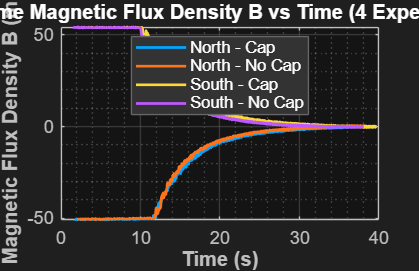


Finished! Saved as: Realtime_Type2_Mode2_All.fig


clc; clear; close all;

%% =========================================================
% 1. SELECTORS & MODES (เลือกสวิตช์การทำงานตรงนี้)
% ==========================================================
plot_type  = 2;     % 1 = พล็อต ADC 12-bit (0-4095) | 2 = พล็อต สนามแม่เหล็ก B (mT)
plot_mode  = 2;     % 1 = พล็อตทีละ 1 การทดลอง    | 2 = พล็อตรวมทั้ง 4 การทดลอง
active_exp = 'SNC'; % สำหรับ plot_mode = 1 เลือก: 'NC' | 'NNC' | 'SC' | 'SNC'


%% =========================================================
% 2. SENSOR & PARAMETERS (พารามิเตอร์เซนเซอร์)
% ==========================================================
params.Vref_mV     = 3300;   % แรงดันอ้างอิง ADC (3300 mV = 3.3V)
params.VQ_mV       = 1650;   % VQ ตั้งต้น (mV) [กรณีไม่ใช้ auto VQ]
params.use_auto_VQ = true;   % true = ดึง VQ จากจุดสุดท้ายอัตโนมัติ | false = ใช้ params.VQ_mV
params.Sens_25     = 30;     % Sensitivity ที่ 25°C (mV/mT)
params.STC         = 0.0012; % STC: สัมประสิทธิ์อุณหภูมิ (%/°C)
params.TA          = 25;     % TA: อุณหภูมิแวดล้อม (°C)


%% =========================================================
% 3. REALTIME FILE PATHS (พาธไฟล์เรียลไทม์ทั้ง 4 หมวด)
% ==========================================================
folder_name = 'realtimeralsignal'; % ชื่อโฟลเดอร์เก็บไฟล์

% ดึงพาธไฟล์จริง (แก้ไขชื่อไฟล์ NNC ไม่ให้ซ้ำกับ NC แล้ว)
files.NC  = resolvePath(folder_name, 'realtimenorthcap.mat');
files.NNC = resolvePath(folder_name, 'realtimenorthnocap.mat');
files.SC  = resolvePath(folder_name, 'realtimesouthcap.mat');
files.SNC = resolvePath(folder_name, 'realtimesouthnocap.mat');

bg_color = [0.12 0.12 0.12];


%% =========================================================
% 4. RUN PROGRAM ACCORDING TO SELECTION
% ==========================================================
if plot_mode == 1
    % ------------------------------------------------------
    % MODE 1: SINGLE EXPERIMENT
    % ------------------------------------------------------
    switch upper(active_exp)
        case 'NC',  active_file = files.NC;  exp_title = 'North - Cap';     line_color = [0 0.65 1];
        case 'NNC', active_file = files.NNC; exp_title = 'North - No Cap';  line_color = [1 0.45 0.1];
        case 'SC',  active_file = files.SC;  exp_title = 'South - Cap';     line_color = [1 0.85 0.2];
        case 'SNC', active_file = files.SNC; exp_title = 'South - No Cap';  line_color = [0.75 0.35 1];
        otherwise, error('Invalid active_exp! Choose NC, NNC, SC, or SNC');
    end

    checkFiles({active_file});
    [t, raw_adc, B_mT] = readRealtimeData(active_file, params);

    figure('Color', bg_color, 'Position', [100 100 850 550]);

    if plot_type == 1
        % พล็อต ADC 12-bit ดิบบอร์ด
        plot(t, raw_adc, 'Color', line_color, 'LineWidth', 1.8, 'DisplayName', exp_title);
        ylabel('Raw ADC Value (12-bit)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
        title(['Realtime ADC 12-bit vs Time: ' exp_title], 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
        ylim([0 4500]);
    elseif plot_type == 2
        % พล็อต Magnetic Flux Density B (mT)
        plot(t, B_mT, 'Color', line_color, 'LineWidth', 1.8, 'DisplayName', exp_title);
        ylabel('Magnetic Flux Density B (mT)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
        title(['Realtime Magnetic Flux Density B vs Time: ' exp_title], 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
    else
        error('Invalid plot_type! Use 1 (ADC 12-bit) or 2 (Magnetic B).');
    end

    xlabel('Time (s)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
    grid on; grid minor; formatAxis(gca);
    legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');

    save_name = sprintf('Realtime_Type%d_Mode1_%s.fig', plot_type, active_exp);
    saveas(gcf, save_name);
    fprintf('\nFinished! Saved as: %s\n', save_name);


elseif plot_mode == 2
    % ------------------------------------------------------
    % MODE 2: ALL 4 EXPERIMENTS
    % ------------------------------------------------------
    checkFiles({files.NC, files.NNC, files.SC, files.SNC});

    [t_NC,  adc_NC,  B_NC]  = readRealtimeData(files.NC,  params);
    [t_NNC, adc_NNC, B_NNC] = readRealtimeData(files.NNC, params);
    [t_SC,  adc_SC,  B_SC]  = readRealtimeData(files.SC,  params);
    [t_SNC, adc_SNC, B_SNC] = readRealtimeData(files.SNC, params);

    figure('Color', bg_color, 'Position', [100 100 850 550]);

    if plot_type == 1
        % พล็อต ADC 12-bit รวมทั้ง 4 การทดลอง
        plot(t_NC,  adc_NC,  'Color', [0 0.65 1],   'LineWidth', 1.6, 'DisplayName', 'North - Cap'); hold on;
        plot(t_NNC, adc_NNC, 'Color', [1 0.45 0.1],  'LineWidth', 1.6, 'DisplayName', 'North - No Cap');
        plot(t_SC,  adc_SC,  'Color', [1 0.85 0.2],  'LineWidth', 1.6, 'DisplayName', 'South - Cap');
        plot(t_SNC, adc_SNC, 'Color', [0.75 0.35 1], 'LineWidth', 1.6, 'DisplayName', 'South - No Cap');
        ylabel('Raw ADC Value (12-bit)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
        title('Realtime Raw ADC 12-bit vs Time (4 Experiments)', 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
        ylim([0 4500]);
    elseif plot_type == 2
        % พล็อต Magnetic Flux Density B (mT) รวมทั้ง 4 การทดลอง
        plot(t_NC,  B_NC,  'Color', [0 0.65 1],   'LineWidth', 1.6, 'DisplayName', 'North - Cap'); hold on;
        plot(t_NNC, B_NNC, 'Color', [1 0.45 0.1],  'LineWidth', 1.6, 'DisplayName', 'North - No Cap');
        plot(t_SC,  B_SC,  'Color', [1 0.85 0.2],  'LineWidth', 1.6, 'DisplayName', 'South - Cap');
        plot(t_SNC, B_SNC, 'Color', [0.75 0.35 1], 'LineWidth', 1.6, 'DisplayName', 'South - No Cap');
        ylabel('Magnetic Flux Density B (mT)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
        title('Realtime Magnetic Flux Density B vs Time (4 Experiments)', 'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
    else
        error('Invalid plot_type! Use 1 (ADC 12-bit) or 2 (Magnetic B).');
    end

    xlabel('Time (s)', 'Color', 'w', 'FontSize', 12, 'FontWeight', 'bold');
    grid on; grid minor; formatAxis(gca);
    legend('show', 'TextColor', 'w', 'Color', [0.2 0.2 0.2], 'EdgeColor', [0.4 0.4 0.4], 'Location', 'best');

    save_name = sprintf('Realtime_Type%d_Mode2_All.fig', plot_type);
    saveas(gcf, save_name);
    fprintf('\nFinished! Saved as: %s\n', save_name);

else
    error('Invalid plot_mode! Use 1 or 2.');
end



%% =========================================================
% LOCAL FUNCTIONS
% ==========================================================
function [t, raw_adc, B_mT] = readRealtimeData(file_path, p)
    data = load(file_path);

    % สกัดค่า t และ raw_adc ด้วยระบบค้นหาอัตโนมัติ
    [t, raw_adc] = findRawAndT(data, file_path);

    % 1. แปลง ADC (0-4095) -> Voltage Output (mV)
    Vout_mV = raw_adc * (p.Vref_mV / 4095);

    % 2. Auto VQ
    if isfield(p, 'use_auto_VQ') && p.use_auto_VQ
        VQ_val = Vout_mV(end);
    else
        VQ_val = p.VQ_mV;
    end

    % 3. คำนวณ Magnetic Flux Density B (mT)
    sens_adj = p.Sens_25 * (1 + p.STC * (p.TA - 25));
    B_mT     = (Vout_mV - VQ_val) / sens_adj;
end


function [t, raw_adc] = findRawAndT(data, file_path)
    fn = fieldnames(data);
    
    % รอบที่ 1: ตรวจหาตัวแปร Sensor_raw_log หรือ out/ans ก่อน
    for i = 1:length(fn)
        val = data.(fn{i});
        if (isstruct(val) || isa(val, 'Simulink.SimulationOutput'))
            if isfield(val, 'Sensor_raw_log') || isprop(val, 'Sensor_raw_log')
                val = val.Sensor_raw_log;
            end
        end
        [t, raw_adc] = unpackSignal(val);
        if ~isempty(raw_adc), return; end
    end
    
    % รอบที่ 2: วนค้นหาทุกตัวแปรที่มีในไฟล์
    for i = 1:length(fn)
        val = data.(fn{i});
        [t, raw_adc] = unpackSignal(val);
        if ~isempty(raw_adc), return; end
    end
    
    % หากไม่พบจะพิมพ์โครงสร้างจริงออกมาดูทาง Command Window
    fprintf('\n❌ โครงสร้างตัวแปรภายในไฟล์ %s:\n', file_path);
    disp(data);
    error('ไม่สามารถอ่านโครงสร้างข้อมูลในไฟล์ %s ได้', file_path);
end


function [t, raw_adc] = unpackSignal(val)
    t = []; raw_adc = [];
    try
        if isa(val, 'Simulink.SimulationData.Dataset')
            elem = val.getElement(1);
            [t, raw_adc] = unpackSignal(elem);
        elseif isprop(val, 'Values')
            [t, raw_adc] = unpackSignal(val.Values);
        elseif isprop(val, 'Data') || (isstruct(val) && isfield(val, 'Data'))
            raw_adc = double(val.Data(:));
            if isprop(val, 'Time') || isfield(val, 'Time')
                t = double(val.Time(:));
            else
                t = (0:length(raw_adc)-1)';
            end
        elseif isstruct(val) && isfield(val, 'signals')
            raw_adc = double(val.signals.values(:));
            t       = double(val.time(:));
        elseif istimetable(val)
            t       = seconds(val.Properties.RowTimes);
            raw_adc = double(val{:, 1});
        elseif isnumeric(val) && ~isempty(val)
            if size(val, 2) >= 2
                t       = double(val(:, 1));
                raw_adc = double(val(:, 2));
            else
                raw_adc = double(val(:));
                t       = (0:length(raw_adc)-1)';
            end
        end
    catch
        t = []; raw_adc = [];
    end
end


function full_path = resolvePath(folder, filename)
    % ค้นหาไฟล์ทั้งจากภายในโฟลเดอร์ realtimeralsignal และใน Root Folder
    sub_path = fullfile(folder, filename);
    if isfile(sub_path)
        full_path = sub_path;
    else
        full_path = filename;
    end
end


function formatAxis(ax)
    ax.Color     = [0.08 0.08 0.08];
    ax.XColor    = [0.75 0.75 0.75];
    ax.YColor    = [0.75 0.75 0.75];
    ax.GridColor = [0.35 0.35 0.35];
    ax.GridAlpha = 0.5;
    ax.FontSize  = 11;
end


function checkFiles(files)
    for k = 1:length(files)
        if ~isfile(files{k})
            error('File not found:\n%s\n\nCurrent Folder:\n%s', files{k}, pwd);
        end
    end
end